# Cvičení 4 - B2M31AEDA

## Nahrání dat

Dejte si pozor na to, aby jste byli v MATLABu ve složce, kde máte umístěn soubor s daty (data.csv), nebo máte složku, ve které je soubor s daty, přidanou do cesty MATLABu (Matlab Path).

T = readtable('data.csv','ReadVariableNames',true);

## 1. Vizualizace dat

% Váš kód pro vizualizaci
t = tiledlayout('flow');

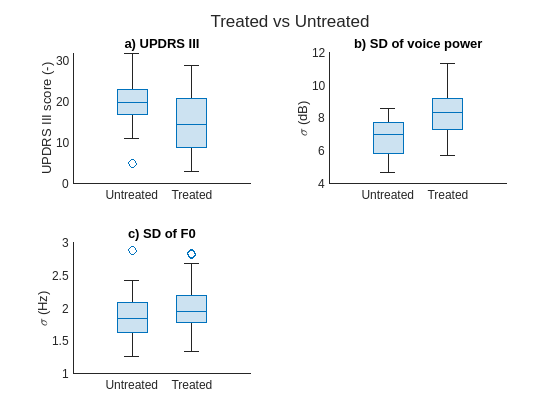

title(t, 'Treated vs Untreated')
nexttile
boxchart([T.UPDRS_III_U, T.UPDRS_III_T])

set(gca, 'XTickLabel', {'Untreated', 'Treated'})
title('a) UPDRS III'); ylabel('UPDRS III score (-)')

nexttile
boxchart([T.stdPWR_U, T.stdPWR_T])

set(gca, 'XTickLabel', {'Untreated', 'Treated'})
title("b) SD of voice power"); ylabel("\sigma (dB)")

nexttile
boxchart([T.stdF0_U, T.stdF0_T])
set(gca, 'XTickLabel', {'Untreated', 'Treated'})
title("c) SD of F0"); ylabel("\sigma (Hz)")

**Otázky:**

- *Vykazují zkoumané skupiny znaky normálního pravděpodobnostního rozdělení? Pokud ne, jaké pozorujete odchylky?*

*a) Oboje vykazuje. Untreate má jeden outlier dolů, bude mírně skewed, nicméně ne výrazně*

*b) Untreated nevykazuje známky norm rozdělení, je značně nakloněná k vyšším hodnotám. Treated je více normální*

*c) Untreated má známky normálního rozdělení až na 1 outlier. Treated má několik outlierů a je nakloněna k nižším hodnotám*

- *Je mezi skupinami treated-untreated viditelný nějaký účinek léků? Je tento účinek pro pacienta zlepšením, nebo zhoršením stavu?*

*Ano je, hlavně v grafech a) a b). Tazo změna ukazuje zlepšení stavu*

## 1b. Ověření normality parametrů stdPWR, stdF0

- *Pouze jednou* zapište korektně hypotézy (H0, H1), které odpovídají vámi vybranému testu normality. Pokud použijete na všechny skupiny stejný test, budou (v principu) hypotézy stále stejné.

- Nastavte si hladinu statistické významnosti α.

- Proveďte testy, **korektně**  reportujte výsledky.

% Váš kód
alpha = 0.05;
[HPwrU, pPwrU, SWsPwrU] = swtest(T.stdPWR_U, alpha);
[HPwrT, pPwrT, SWsPwrT] = swtest(T.stdPWR_T, alpha);
[HF0U, pF0U, SWsF0U] = swtest(T.stdF0_U, alpha);
[HF0T, pF0T, SWsF0T] = swtest(T.stdF0_T, alpha);

### Hypotézy, reporty:

H0: Data D jsou normálně rozdělena.

α: 5%

stdPWR_U (W = 0.96, p=0.64)

stdPWR_T (W = 0.98, p=0.97)

stdF0_U (W = 0.95, p=0.48)

stdF0_T (W = 0.91, p=0.11)

## 2. Manuální implementace párového t-testu


$$t=\ \frac{\mu_{\Delta \mathit{\mathbf{x}}} }{\sigma_{\Delta \mathit{\mathbf{x}}} /\sqrt{n}}\ ;\ \Delta \mathit{\mathbf{x}}={\mathit{\mathbf{x}}}_U -{\mathit{\mathbf{x}}}_T$$


% Váš kód
% help tcdf
function [p, t] = ttestman(xu, xt)
    dx = xu-xt;
    mudx = mean(dx);
    sdx = std(dx);
    n = length(dx);

    t = mudx/(sdx/sqrt(n));

    p = 2*(1-tcdf(t, n-1));
end

[p, t] = ttestman(T.UPDRS_III_U, T.UPDRS_III_T);

### **Hypotézy, reporty:**

- **Navrhněte a slovy zapište hypotézy (H0, H1)**

- **Nastavte hodnotu α**

- **Proveďte párový t-test za pomocí vaší implementace**

- **Zjistěte příslušnou *****p*****-hodnotu **

- **Korektně reportujte výsledky**

- **Stručně interpretujte**

H0: rozdíl skore před a po podání léku má normální rozdělení

alpha = 0.05

t(15) =2.4528, p=0.027

Hypotézu zamítáme

## 3. Úloha

K následujícím otázkám navrhněte hypotézy, hodnoty α, proveďte analýzy pomocí vhodných statistických testů a stejně jako v předchozích částech výsledky správně reportujte a vyvoďte závěry.

- *Má podání léků vliv na řeč pacientů s PN z hlediska toho, jak moc dokáží měnit hlasitost svého projevu? Jaký je tento vliv (pozitivní/negativní,  silný/slabý, …)?*

- *Má podání léků vliv na monotónnost řeči pacientů s PN? Jaký je tento vliv (pozitivní/negativní,  silný/slabý, …)?*

- *Uvažujme ****pouze hodnoty naměřené před podáním léků.****Odráží automaticky naměřené hodnoty parametrů *stdPWR* a *stdF0* u jednotlivých pacientů jejich skóre z lékařem vyplněného dotazníku UPDRS? ***Pomocí vhodného zobrazení vykreslete ****vztah**** mezi všemi dvojicemi.**

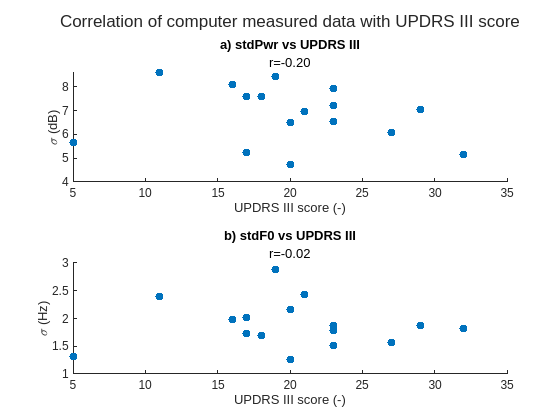

% Váš kód
% 1
alpha = 0.05;
% a
[H1left,P1left,CI1left,STATS1left] = ttest(T.stdPWR_U, T.stdPWR_T,"Alpha",alpha,'Tail','left');
% b
[H1right,P1rigt,CI1right,STATS1right] = ttest(T.stdPWR_U, T.stdPWR_T,"Alpha",alpha,'Tail','right');

% 2
% a
[H2left,P2left,CI2left,STATS2left] = ttest(T.stdF0_U, T.stdF0_T,"Alpha",alpha,'Tail','left');
% b
[H2right,P2rigt,CI2right,STATS2right] = ttest(T.stdF0_U, T.stdF0_T,"Alpha",alpha,'Tail','right');

%3
figure
t = tiledlayout("vertical");
title(t, 'Correlation of computer measured data with UPDRS III score')
nexttile
r = corr(T.UPDRS_III_U, T.stdPWR_U, 'Type','Pearson');
scatter(T.UPDRS_III_U, T.stdPWR_U, 'o', 'filled');
xlabel('UPDRS III score (-)'); ylabel('\sigma (dB)');
title("a) stdPwr vs UPDRS III")
subtitle(sprintf('r=%.2f', r))

nexttile
r = corr(T.UPDRS_III_U, T.stdF0_U, 'Type','Pearson');
scatter(T.UPDRS_III_U, T.stdF0_U, 'o', 'filled');
xlabel('UPDRS III score (-)'); ylabel('\sigma (Hz)');

title("b) stdF0 vs UPDRS III")
subtitle(sprintf('r=%.2f', r))

### Hypotézy, reporty:

- **Navrhněte a slovy zapište hypotézy (H0, H1)**

1,2)

H0: Průměr rozdílů hodnot před a po léčbě je nulový. 

a)

H1: Průměr rozdílů je menší než 0

b)

H1: Průměr rozdílů je větší než 0

- **Nastavte hodnotu α**

α = 5%

- **Proveďte statistické testy**

- **Korektně reportujte výsledky**

1a) t(15)=-6.1422, p=9.4e-06

1b) t(15)=-6.1422, p = 1

2a) t(15)=-1.2460, p = 0.1159

2b) t(15)=-1.2460, p = 0.8841

- **Stručně interpretujte**

1) Průměrná odchylka je po léčbě výrazně nižší

2) Průměrná odchylka je po léčbě téměř stejná